# Chapitre 7 : Optimum filters

## Ex 7.4 : Kalman filter - Body in gravitation

Let's assume that a body is ejected in the air with a constant velocity v = 10 [m/s] at a given angle $\alpha =40\;\textrm{degrees}$

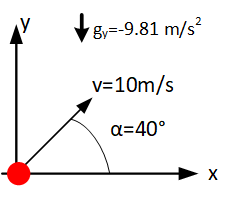

The goal is to estimate the trajectory (position(x,y)). The position (x,y) of the ball across time is measured but the measurment is very noisy. The goal is to filter the noise with the Kalman filter.

clear; close all; clc;
%rng default; % not used, "random" noise come from mat file
data=load('ex74_data.mat');

## Generate Trajectory

### Parameters

Definition of the parameters:

g = 9.81;       % [m/s2] gravitation
v = 10;         % [m/s] initial speed
dt = 2e-3;
alpha = 40;
sigmaV = 0.2;
tmax = 2;
N = round(tmax/dt);
n = 0:N-1;

param = table(g,v,dt,alpha,sigmaV,tmax,N)

param = 1×7 table
     g      v      dt      alpha    sigmaV    tmax     N  
    ____    __    _____    _____    ______    ____    ____

    9.81    10    0.002     40       0.2       2      1000


### Dynamics state

- The Newton law with the simplest discretisation gives:


$$\left\lbrace \begin{array}{ll}
x\left\lbrack k\right\rbrack  & =\;x\left\lbrack k-1\right\rbrack +v_x \left\lbrack k-1\right\rbrack \cdot \Delta t\\
v_x \left\lbrack k\right\rbrack  & {=\;v}_x \left\lbrack k-1\right\rbrack \\
y\left\lbrack k\right\rbrack  & =y\left\lbrack k-1\right\rbrack +v_y \left\lbrack k-1\right\rbrack \cdot \Delta t+\frac{1}{2}a_y \left\lbrack k-1\right\rbrack \Delta t^2 \\
v_y \left\lbrack k\right\rbrack  & {=\;v}_y \left\lbrack k-1\right\rbrack +a_y \left\lbrack k-1\right\rbrack \cdot \Delta t\\
a_y \left\lbrack k\right\rbrack  & =a_y \left\lbrack k-1\right\rbrack 
\end{array}\right.$$


            where the acceleration is the gravity $a_y \left\lbrack k\right\rbrack =-g=-9\ldotp 81\frac{m}{s^2 }$.

            Those equations can be written in matrix shape:


$$\left\lbrack \begin{array}{c}
x\left\lbrack k\right\rbrack \\
v_x \left\lbrack k\right\rbrack \\
y\left\lbrack k\right\rbrack \\
v_y \left\lbrack k\right\rbrack \\
a_y \left\lbrack k\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & \Delta t & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0\\
0 & 0 & 1 & \Delta t & \frac{1}{2}\Delta t^2 \\
0 & 0 & 0 & 1 & \Delta t\\
0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x\left\lbrack k-1\right\rbrack \\
v_x \left\lbrack k-1\right\rbrack \\
y\left\lbrack k-1\right\rbrack \\
v_y \left\lbrack k-1\right\rbrack \\
a_y \left\lbrack k-1\right\rbrack 
\end{array}\right\rbrack$$


            And finally in the compact form:


$$\mathit{\mathbf{X}}\left\lbrack k\right\rbrack =\mathit{\mathbf{F}}\cdot \mathit{\mathbf{X}}\left\lbrack k-1\right\rbrack \;$$


            Where **F** is the transition matrix and **X**[k] is the current state and **X**[k-1] is the previous state.

- The position (x,y) of the ball is measured in the presence of a disturbance (**vn**[k]) where the noise is normally distributed with unit variance ($N\left(0,R\right)\;\;\textrm{where}\;R=\left\lbrack \begin{array}{cc}
\sigma_x^2  & 0\\
0 & \sigma_y^2 
\end{array}\right\rbrack$).


$$\left\lbrack \begin{array}{c}
z_x \left\lbrack k\right\rbrack \\
z_y \left\lbrack k\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left\lbrack k\right\rbrack \\
v_x \left\lbrack k\right\rbrack \\
y\left\lbrack k\right\rbrack \\
v_y \left\lbrack k\right\rbrack \\
a_y \left\lbrack k\right\rbrack 
\end{array}\right\rbrack +\textrm{vn}\left\lbrack k\right\rbrack$$


                And finally, in compact form:


$$\mathit{\mathbf{z}}\left\lbrack k\right\rbrack =\mathit{\mathbf{H}}\cdot \mathit{\mathbf{X}}\left\lbrack k\right\rbrack +\textrm{vn}\left\lbrack k\right\rbrack$$


- To generate the trajatectory, the initial state has to be also defined:


$$\mathit{\mathbf{X}}\left\lbrack 0\right\rbrack =\left\lbrack \begin{array}{c}
x\left\lbrack 0\right\rbrack \\
v_x \left\lbrack 0\right\rbrack \\
y\left\lbrack 0\right\rbrack \\
v_y \left\lbrack 0\right\rbrack \\
a_y \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
v\cdot \left(\cos \left(40°\right)\right)\\
0\\
v\cdot \left(\sin \left(40°\right)\right)\\
-g
\end{array}\right\rbrack$$


Using those equations, the trajetory can be generated.

% Transition state matrix (A)
F = eye(5);
F(1,2)=dt; F(3,4)=dt; F(4,5)=dt;
F(3,5)=0.5*dt^2;

% Input dynamic matrix (B)
G = 0;

% Observation matrix (C)
H = zeros(2,5);
H(1,1)=1; H(2,3)=1;

% initial state
xHatInit = [0; v*cosd(alpha); 0; v*sind(alpha); -g];

disp('F='); disp(F); disp('H='); disp(H); disp('X[0]'); disp(xHatInit)

F=
    1.0000    0.0020         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000    0.0020    0.0000
         0         0         0    1.0000    0.0020
         0         0         0         0    1.0000

H=
     1     0     0     0     0
     0     0     1     0     0

X[0]
         0
    7.6604
         0
    6.4279
   -9.8100



### Generation

Build the transition matrix F and H and the state vector X for N states. Add the measurement noise to the vector x and y (from mat file).

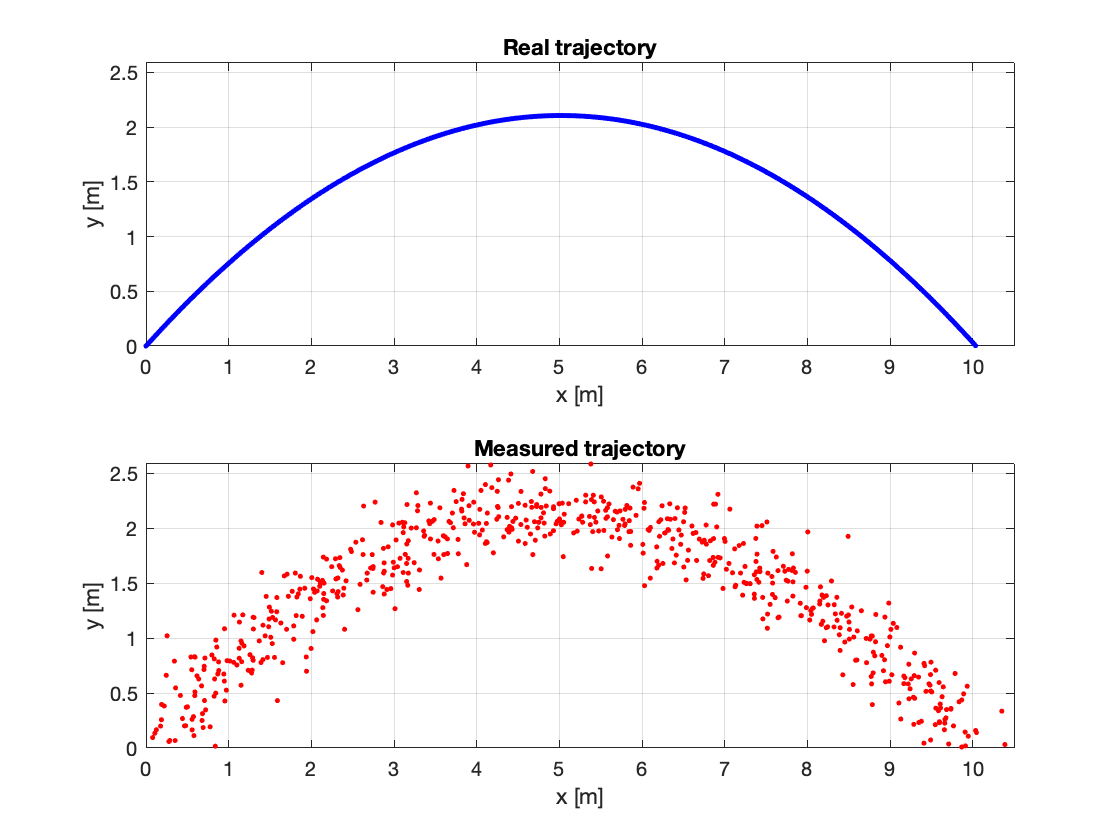

% matrix of state: X
X = zeros(length(xHatInit),N);
X(:,1) = xHatInit;
for k=2:N
    X(:,k) = F*X(:,k-1);
end

% matrix of position without noise: Z
Z = H*X;
Znoisy = Z+[data.noiseX; data.noiseY];
Z = table(Z(1,:)', Z(2,:)');
Z.Properties.VariableNames = ["x","y"];
Znoisy = table(Znoisy(1,:)', Znoisy(2,:)');
Znoisy.Properties.VariableNames = ["x","y"];

figure;
ax1 = nexttile;
    plot(Z.x, Z.y, '.b')
    title('Real trajectory')
    xlabel('x [m]')
    ylabel('y [m]')
    grid;

ax2 = nexttile;
    plot(Znoisy.x, Znoisy.y, '.r')
    title('Measured trajectory')
    xlabel('x [m]')
    ylabel('y [m]')
    grid;
linkaxes([ax1,ax2], 'xy');
ax1.XLim=[0, 10.5];
ax1.YLim=[0, max(Znoisy.y)];

## Kalman filter

### Parameters

The Kalman filter needs the following parameters:

- **F** : Transition Matrix [p x p]

- **H** : Measurement Matrix [q x p]

- **x**(0|0) : Initial state [p x 1]

- **z**[k] : Measurement matrix [q x 1]

- **Qw** : Covariance matrix process noise [p x p]

- **Qv** : Covariance matrix measurement noise [q x q]

- **P**(0|0) : Covariance matrix error [p x p]

where p=5 is the number of state and q=2 is the number of measurement. 

Each of those matrices are known and were already defined during the trajectory generation except **Qw**, **Qv **and **P**(0|0).

Those matrices are defined as following:


$$\begin{array}{l}
Q_v =\left\lbrack \begin{array}{cc}
\sigma_v^2  & 0\\
0 & \sigma_v^2 
\end{array}\right\rbrack \\
Q_w =0\\
P\left(0|0\right)=\left\lbrack \begin{array}{ccc}
1 & \ldotp \ldotp \ldotp  & 0\\
\cdots  & \ddots  & \cdots \\
0 & \cdots  & 1
\end{array}\right\rbrack 
\end{array}$$


% white noise of measurement
Qv=[sigmaV^2, 0; 0, sigmaV^2];
% process noise supposed=0
Qw=0;
% covariance matrix error, perfect at the beginning
P0=eye(size(F,1));

disp('Qv='); disp(Qv); disp('Qw='); disp(Qw); disp('P(0|0)='); disp(P0);

Qv=
    0.0400         0
         0    0.0400

Qw=
     0

P(0|0)=
     1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1



### Kalman recursivity

Those matrices are necessary to create the kalman recursivity where the following matrix are computed:

- $\hat{\mathit{\mathbf{X}}} \left\lbrack k|k-1\right\rbrack$ : State estimation at the sample $k$ based on the measurement up to $k-1$  $[p \times 1]$

- $\mathit{\mathbf{P}}\left\lbrack k|k-1\right\rbrack$ : Error covariance at the sample $k$ based on the measurement up to $k-1$  $[p \times p]$

- $\mathit{\mathbf{K}}\left\lbrack k\right\rbrack$ : Kalman gain computed by minimizing the innovation (noise) on the measurement up to $k$ $[p \times q]$

- $\mathit{\mathbf{P}}\left\lbrack k|k\right\rbrack$ :  Error covariance at the sample $k$ based on the measurement up to $k$  $[p \times p]$

- $\hat{\mathit{\mathbf{X}}} \left\lbrack k|k\right\rbrack$ : State estimation at the sample $k$ based on the measurement up to $k$  $[p \times 1]$

The calculation can be realized in two steps on a loop of each sample measured:

- Predict (based on $n-1$ measurement samples):


$$\begin{array}{l}
\hat{\mathit{\mathbf{X}}} \left\lbrack k|k-1\right\rbrack =\mathit{\mathbf{F}}\cdot \;\hat{\mathit{\mathbf{X}}} \left\lbrack k-1|k-1\right\rbrack \\
\left.\mathit{\mathbf{P}}\left\lbrack k\right|k-1\right\rbrack =\mathit{\mathbf{F}}\cdot \mathit{\mathbf{P}}\left\lbrack k-1\left|k-1\right.\right\rbrack \cdot {\mathit{\mathbf{F}}}^T +{\mathit{\mathbf{Q}}}_w 
\end{array}$$


- Update (based on $n$ measurement samples and the innovation error):


$$\begin{array}{l}
\left.\mathit{\mathbf{K}}\left\lbrack k\right\rbrack =\mathit{\mathbf{P}}\left\lbrack k\right|k-1\right\rbrack \cdot {\mathit{\mathbf{H}}}^T {\left\lbrack \left.\mathit{\mathbf{H}}\cdot \mathit{\mathbf{P}}\left\lbrack k\right|k-1\right\rbrack \cdot {\mathit{\mathbf{H}}}^T +{\mathit{\mathbf{Q}}}_v \right\rbrack }^{-1} \\
\left.\mathit{\mathbf{P}}\left\lbrack k|k\right\rbrack =\left(\mathit{\mathbf{I}}-\mathit{\mathbf{K}}\left\lbrack k\right\rbrack \cdot \mathit{\mathbf{H}}\right)\cdot \mathit{\mathbf{P}}\left\lbrack k\right|k-1\right\rbrack \\
\hat{\mathit{\mathbf{X}}} \left\lbrack k|k\right\rbrack =\hat{\mathit{\mathbf{X}}} \left\lbrack k|k-1\right\rbrack +\mathit{\mathbf{K}}\left\lbrack k\right\rbrack \cdot \left\lbrack \mathit{\mathbf{z}}\left\lbrack k\right\rbrack -\mathit{\mathbf{H}}\cdot \hat{\mathit{\mathbf{X}}} \left\lbrack k|k-1\right\rbrack \right\rbrack \;
\end{array}$$


Build the function *KalmanGain* with inputs  : **x**(0|0), **P**(0|0), $\mathbf{z}[k]$ and with the outputs : **K, **$\hat{\mathit{\mathbf{X}}} \left\lbrack k|k\right\rbrack$, $\mathit{\mathbf{P}}\left\lbrack k|k\right\rbrack$.

% Build the function to compute the Kalman Gain and the estimated state
% vector.
[K, xHat, P] = kalmanGain(F, H, Qw, Qv, xHatInit, P0, [Znoisy.x';Znoisy.y']);

### Estimation results

Finally, the prediction is obtained with Kalman filter. Each parameters of the state vector can be displayed accross time. In the following example, we are looking only the estimated position ($\hat{x}$, $\hat{y}$).


$$\begin{array}{l}
\hat{x} =\hat{\mathit{\mathbf{X}}} \left\lbrack 0\right\rbrack \\
\hat{y} =\hat{\mathit{\mathbf{X}}} \left\lbrack 2\right\rbrack 
\end{array}$$


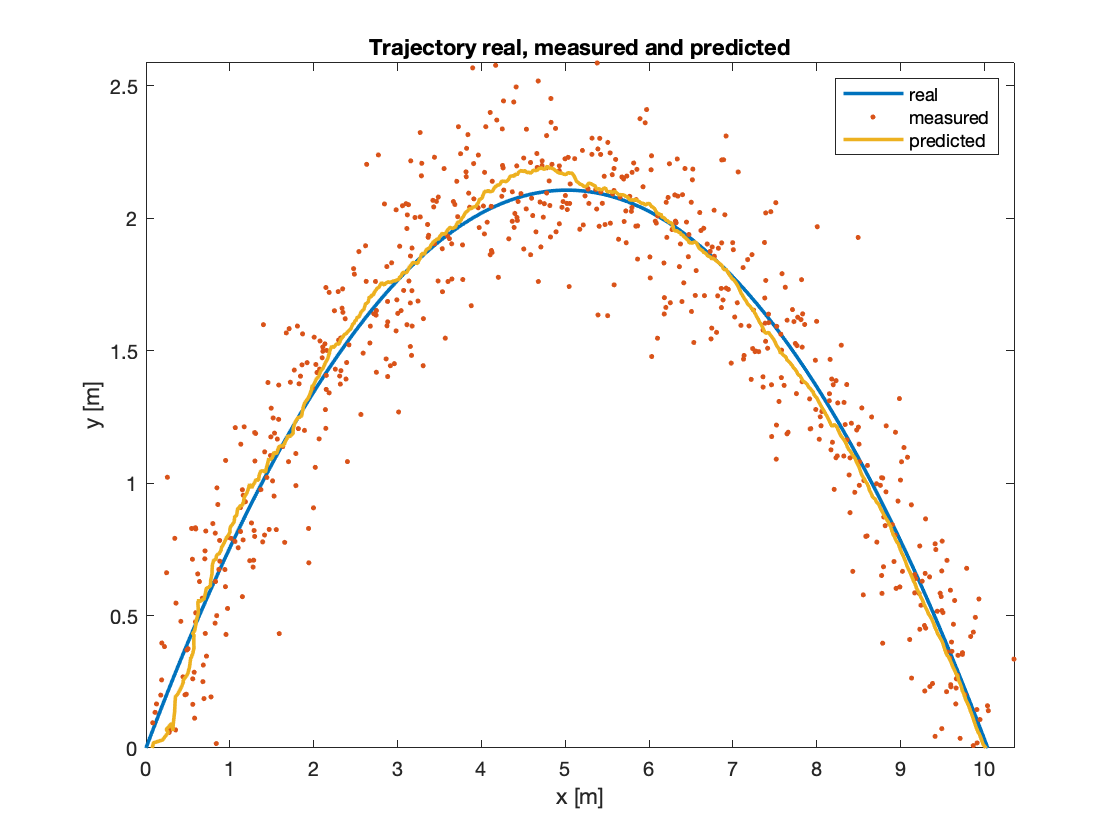

% Zestim et en faite xHat avec que posx et posy
Zestim = H*xHat;
Zestim = table(Zestim(1,:)', Zestim(2,:)');
Zestim.Properties.VariableNames = ["x","y"];

figure;
plot(Z.x,Z.y, '-', ...
     Znoisy.x, Znoisy.y, '.', ...
     Zestim.x, Zestim.y, '-', 'Linewidth', 1.8)
title('Trajectory real, measured and predicted')
legend('real', 'measured', 'predicted')
xlim([0,max(Znoisy.x(Z.y>0))])
ylim([0,max(Znoisy.y)])
xlabel('x [m]')
ylabel('y [m]')

The others parameters as the Kalman gain and the error covariance matrix can be also displayed:

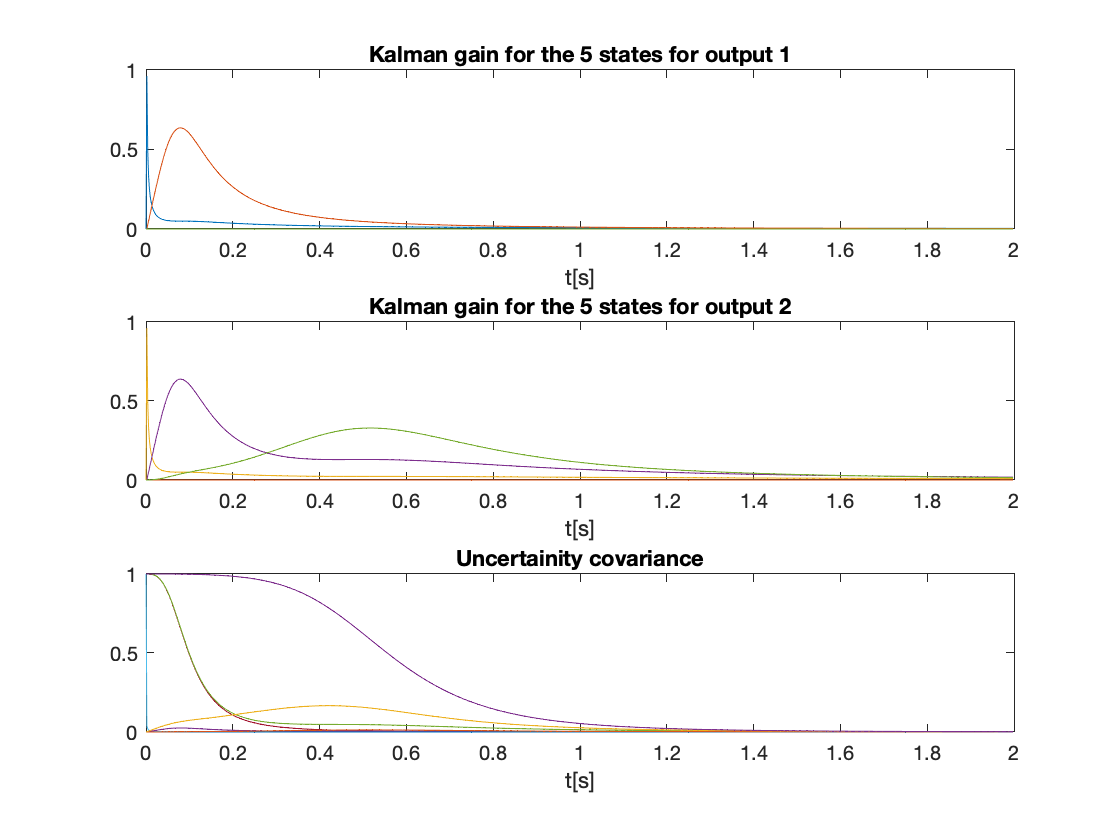

Koutput1 = squeeze(K(:,1,:));
Koutput2 = squeeze(K(:,2,:));
figure;
subplot(3,1,1)
    plot(n*dt, Koutput1')
    title('Kalman gain for the 5 states for output 1')
    xlabel('t[s]')
subplot(3,1,2)
    plot(n*dt, Koutput2')
    title('Kalman gain for the 5 states for output 2')
    xlabel('t[s]')
subplot(3,1,3)
    plot(n*dt, reshape(P, [25,N]))
    title('Uncertainity covariance')
    xlabel('t[s]')